# 程序说明

实例 4.8-1 功能：构建含短路连接的卷积神经网络，对含有0~9数字的二值图像（像素为28×28）进行分类，并计算分类准确率 作者：zhaoxch_mail@sina.com 时间：2020年3月22日 版本：DLTEX801-V1

## 清除内存、清除屏幕

clear
clc

## 建立网络层主体

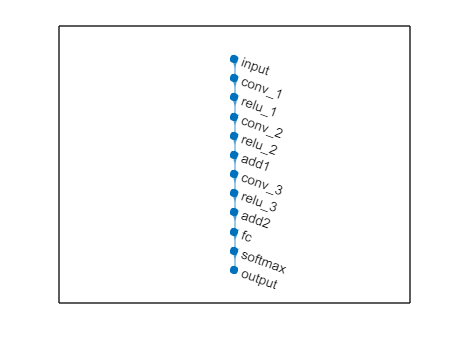

layers = [
    imageInputLayer([28 28 1],'Name','input')
    
    convolution2dLayer(5,16,'Padding','same','Name','conv_1')
%     batchNormalizationLayer('Name','BN_1')
    reluLayer('Name','relu_1')
    
%     convolution2dLayer(3,32,'Padding','same','Stride',2,'Name','conv_2')
    convolution2dLayer(3,16,'Padding','same','Stride',1,'Name','conv_2')

%     batchNormalizationLayer('Name','BN_2')
    reluLayer('Name','relu_2')
    additionLayer(2,'Name','add1')
    convolution2dLayer(3,16,'Padding','same','Name','conv_3')
%     batchNormalizationLayer('Name','BN_3')
    reluLayer('Name','relu_3')
    
    additionLayer(2,'Name','add2')
    
%     averagePooling2dLayer(2,'Stride',2,'Name','avpool')
    fullyConnectedLayer(10,'Name','fc')
    softmaxLayer('Name','softmax')
%     classificationLayer('Name','classOutput')];
    classificationLayer('Name','output')];
% 创建并显示网络
lgraph = layerGraph(layers);
figure
plot(lgraph)

## 建立短路连接层

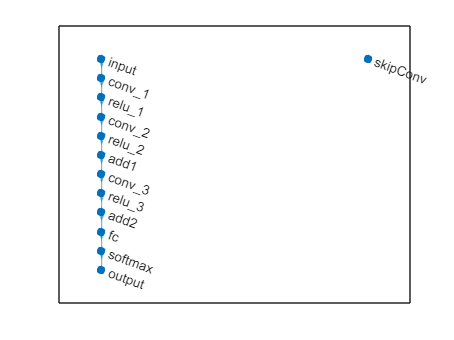

skipConv = convolution2dLayer(1,16,'Padding','same','Stride',1,'Name','skipConv');
lgraph = addLayers(lgraph,skipConv);
figure
plot(lgraph)

## 进行连接并绘制网络结构图谱

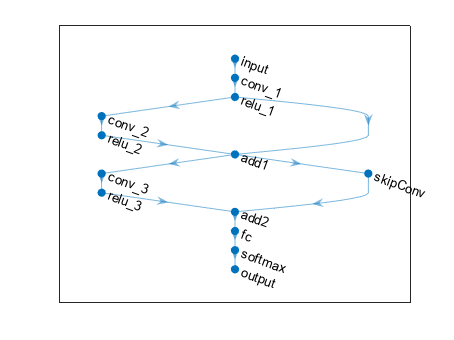

%lgraph = connectLayers(lgraph,'relu_1','add1/in2');
lgraph = connectLayers(lgraph,'relu_1','add1/in2');
lgraph = connectLayers(lgraph,'add1','skipConv');
lgraph = connectLayers(lgraph,'skipConv','add2/in2');
figure
plot(lgraph);

analyzeNetwork(lgraph)

## 加载训练和验证数据

[XTrain,YTrain] = digitTrain4DArrayData;
[XValidation,YValidation] = digitTest4DArrayData;

## 配置训练参数并训练网络

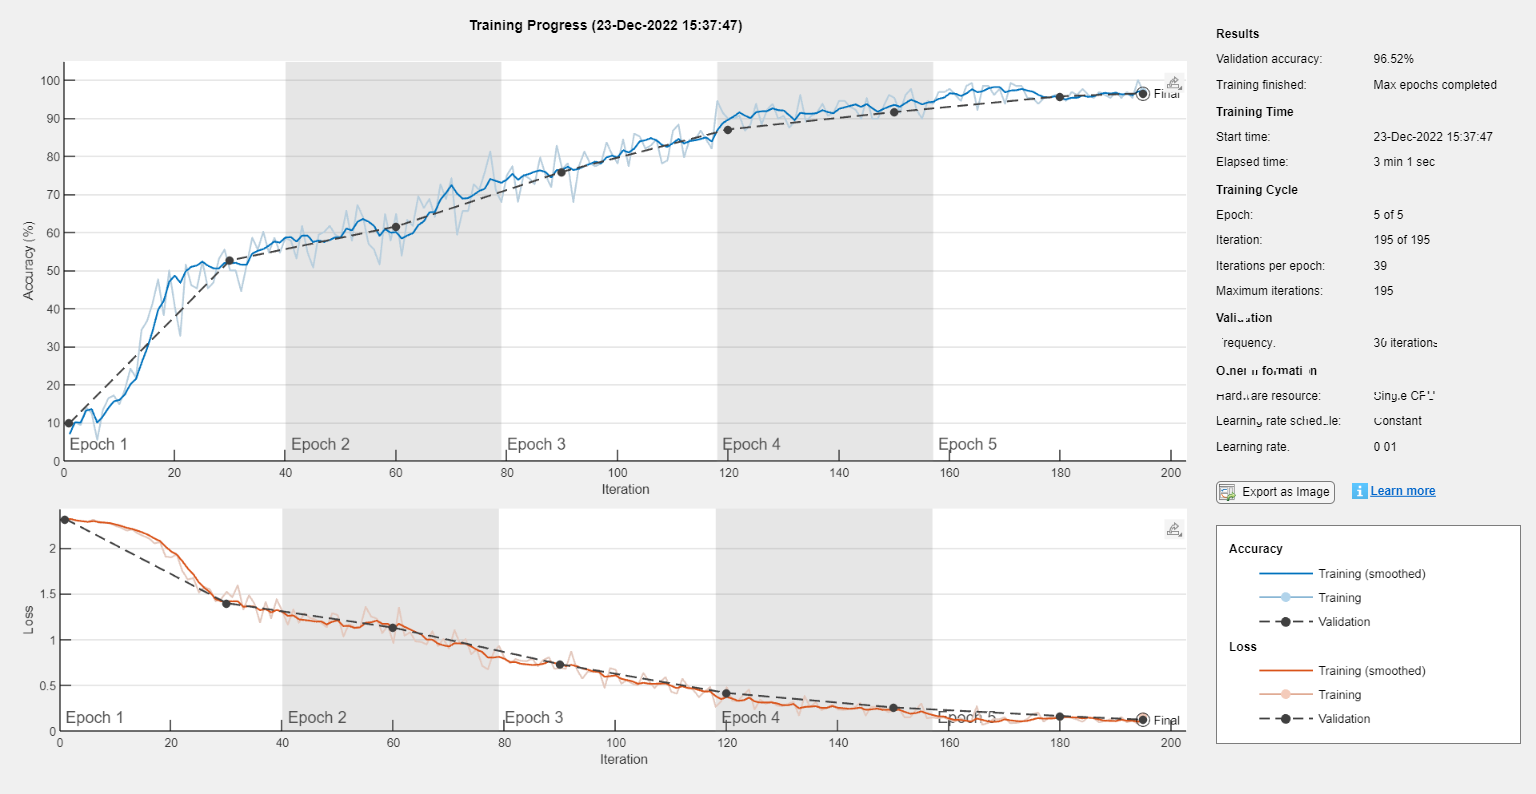

options = trainingOptions('sgdm', ...
    'MaxEpochs',5, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{XValidation,YValidation}, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');
net = trainNetwork(XTrain,YTrain,lgraph,options);

## 显示网络信息

net

net =   DAGNetwork with properties:

         Layers: [13×1 nnet.cnn.layer.Layer]
    Connections: [14×2 table]
     InputNames: {'input'}
    OutputNames: {'output'}


## 对验证集进行分类并计算准确率

YPredicted = classify(net,XValidation);
accuracy = mean(YPredicted == YValidation)

accuracy = 0.9652